A vehicle is moving at a constant speed of 96km/hour. A user in the vehicle receives wireless signals with carrier frequency 900MHz from a cellular base station. The signal bandwidth is assumed to be 30 KHz. Assume that the wireless channel between the user and the base station experiences flat Rayleigh fading. 

(1)  (1 point) Determine the maximum Doppler frequency and the normalized maximum Doppler frequency of the wireless channel. 

clc;
close all;
clear all;
Speed = convvel(96,'km/h','m/s');
fc = 900e6;
lambda = (3*(10^8))/fc;
fdmax = Speed/lambda

fdmax =                         80


BW = 30e3;
Ts = 1/BW; %assuming that the given bandwidth is single sided
Nfdmax = fdmax * Ts

Nfdmax =        0.00266666666666667


(2)  (3 points) Use Jakes' fading simulator (with *M = 8 *oscillators or *N = 34*) to generate the Rayleigh fading channel. Plot the amplitude of the first 200 channel samples (showing the channel amplitude | *h*(*t*) | in dB). Also plot the amplitude of the first 8000 channel samples in a separated figure. (Note: Normalize the channel samples such that the average power of each sample is 1.) 

clc;
close all;
clear all;
M = 8; %Given
N = 34; %Given
Ts = 3.333e-5; %From previous question
k = 1:1:200; %because we need 200 samples
format long g; %for better accuracy
t = k*Ts; %Time stamps
ht = 0;
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    fdmax = 80; %maximum Doppler Frequency from previous question
    h = exp(1j*Bn)*(cos(2*pi*t*fdmax*cos(thetan))); %Expression of h(t) without summation part for single fading channel
    ht = ht + h;
    
    E0 = (abs(power(ht,2)))/k; %Normalization of channel sample
    hkamp = ht/sqrt(E0);
    hkindb = 10*log10((hkamp));
    
end
set(gcf,'position',[10,10,900,300])
tiledlayout(1,2)
nexttile
plot(k,real(hkindb))
title("Jake's Fading Simulator for 200 samples wrt samples")
xlabel("No. OF SAMPLES")
ylabel("|h(t)| IN dB")
nexttile
plot(t,real(hkindb))
title("Jake's Fading Simulator for 200 samples wrt Time")
xlabel("Time in seconds")
ylabel("|h(t)| IN dB")


clc;
close all;
clear all;
M = 8;
N = 34;
Ts = 3.333e-5;
k = 1:1:8000;
format long g;
t = k*Ts;
ht = 0;
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    fdmax = 80;
    h = exp(1j*Bn)*(cos(2*pi*t*fdmax*cos(thetan)));
    ht = ht + h;
    
    E0 = (abs(power(ht,2)))/k;
    hkamp = ht/sqrt(E0);
    hkindb = 10*log10((hkamp));
    
end
set(gcf,'position',[10,10,900,300])
tiledlayout(1,2)
nexttile
plot(k,real(hkindb))
title("Jake's Fading Simulator for 8000 samples wrt samples")
xlabel("No. OF SAMPLES")
ylabel("|h(t)| IN dB")
nexttile
plot(t,real(hkindb))
title("Jake's Fading Simulator for 8000 samples wrt Time")
xlabel("Time in seconds")
ylabel("|h(t)| IN dB")

                                                                                        **                       AN ALTERNATE APPROACH**

clc;
close all;
clear all;
M = 8;
N = 34;
Ts = 3.333e-5;
k = 1:1:200;
syms k n;
format long g;
t = k*Ts;
hk = 0;
%STEP 1 Calculating h(k)
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    fdmax = 80;
    h = exp(1j*Bn)*(cos(2*pi*t*fdmax*cos(thetan)));
    hk = hk + h;
end
hk = vpa(hk); %Simplifying h(k) using variable precision aritmatic
%STEP 2 Finding Eo for Normalization of channel samples
Eo = 0;
for m = 1:1:200
    temp = abs(power(subs(hk,k,m),2))/200;
    Eo = Eo + temp;
end
Eo = vpa(Eo);
%STEP 3 Finding Normalized H(k)
hK = zeros(1,200);
for a = 1:1:200
    temp = subs(hk,k,a)/sqrt(Eo);
    hK(a) = temp;
end
%STEP 4 finding H(k) in dB
hk_db = 10*log10(hK);


set(gcf,'position',[10,10,900,300])
tiledlayout(1,2)
nexttile
plot(1:1:200,(real(hk_db)))
title("Jake's Fading Simulator for 200 samples wrt samples")
xlabel("No. OF SAMPLES")
ylabel("|h(t)| IN dB")
nexttile
plot(1*Ts:Ts:200*Ts,real(hk_db))
title("Jake's Fading Simulator for 200 samples wrt Time")
xlabel("Time in seconds")
ylabel("|h(t)| IN dB")

clc;
close all;
clear all;
M = 8;
N = 34;
Ts = 3.333e-5;
k = 1:1:8000;
syms k n;
format long g;
t = k*Ts;
hk = 0;
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    fdmax = 80;
    h = exp(1j*Bn)*(cos(2*pi*t*fdmax*cos(thetan)));
    hk = hk + h;
end
hk = vpa(hk);
Eo = 0;
for m = 1:1:8000
    temp = abs(power(subs(hk,k,m),2))/8000;
    Eo = Eo + temp;
end
Eo = vpa(Eo);
hK = zeros(1,8000);
for a = 1:1:8000
    temp = subs(hk,k,a)/sqrt(Eo);
    hK(a) = temp;
end
hk_db = 10*log10(hK);


set(gcf,'position',[10,10,900,300])
tiledlayout(1,2)
nexttile
plot(1:1:8000,(real(hk_db)))
title("Jake's Fading Simulator for 8000 samples wrt samples")
xlabel("No. OF SAMPLES")
ylabel("|h(t)| IN dB")
nexttile
plot(1*Ts:Ts:8000*Ts,real(hk_db))
title("Jake's Fading Simulator for 8000 samples wrt Time")
xlabel("Time in seconds")
ylabel("|h(t)| IN dB")

(3)  (3 points) Use Jakes' fading simulator (with *M = 8 *oscillators or *N = 34*) to generate a Rayleigh fading channel with a normalized maximum Doppler frequency of *f**D*,max*T**s = *0.1. Plot the amplitude of the first 200 channel samples (showing the channel amplitude | *h*(*t*) | in dB). Compare this figure with the two figures in Question (2). What do you observe? Any explanation? 	

clc;
close all;
clear all;
M = 8;
N = 34;
k = 1:1:200;
format long g;
ht = 0;
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    Nfdmax = 0.1; %Normalized Max. doppeler frequency 
    h = exp(1j*Bn)*(cos(2*pi*k*Nfdmax*cos(thetan)));   %t = k.Ts  t.fdmax = k.Ts.fdmax = k.Nfdmax where Nfdmax is normalized doppler frequency
    ht = ht + h;
    
    E0 = (abs(power(ht,2)))/k;
    hkamp = ht/sqrt(E0);
    hkindb = 10*log10((hkamp));
    
end
set(gcf,'position',[10,10,900,300])
plot(k,real(hkindb))
title("Jake's Fading Simulator for 200 samples wrt samples")
xlabel("No. OF SAMPLES")
ylabel("|h(t)| IN dB")

clc;
close all;
clear all;
M = 8;
N = 34;
k = 1:1:8000;
format long g;
ht = 0;
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    Nfdmax = 0.1;
    h = exp(1j*Bn)*(cos(2*pi*k*Nfdmax*cos(thetan)));
    ht = ht + h;
    
    E0 = (abs(power(ht,2)))/k;
    hkamp = ht/sqrt(E0);
    hkindb = 10*log10((hkamp));
    
end
set(gcf,'position',[10,10,900,300])
plot(k,real(hkindb))
title("Jake's Fading Simulator for 8000 samples wrt samples")
xlabel("No. OF SAMPLES")
ylabel("|h(t)| IN dB")

                                                                                                                ** AN ALTERNATIVE APPROACH**

clc;
close all;
clear all;
M = 8;
N = 34;
Ts = 3.333e-5;
k = 1:1:200;
syms k n;
format long g;
hk = 0;
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    Nfdmax = 0.1;
    h = exp(1j*Bn)*(cos(2*pi*k*Nfdmax*cos(thetan)));
    hk = hk + h;
end
hk = vpa(hk);
Eo = 0;
for m = 1:1:200
    temp = abs(power(subs(hk,k,m),2))/200;
    Eo = Eo + temp;
end
Eo = vpa(Eo);
hK = zeros(1,200);
for a = 1:1:200
    temp = subs(hk,k,a)/sqrt(Eo);
    hK(a) = temp;
end
hk_db = 10*log10(hK);


set(gcf,'position',[10,10,900,300])
plot(1:1:200,(real(hk_db)))
title("Jake's Fading Simulator for 200 samples wrt samples")
xlabel("No. OF SAMPLES")
ylabel("|h(t)| IN dB")

clc;
close all;
clear all;
M = 8;
N = 34;
Ts = 3.333e-5;
k = 1:1:8000;
syms k n;
format long g;
hk = 0;
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    Nfdmax = 0.1;
    h = exp(1j*Bn)*(cos(2*pi*k*Nfdmax*cos(thetan)));
    hk = hk + h;
end
hk = vpa(hk);
Eo = 0;
for m = 1:1:8000
    temp = abs(power(subs(hk,k,m),2))/8000;
    Eo = Eo + temp;
end
Eo = vpa(Eo);
hK = zeros(1,8000);
for a = 1:1:8000
    temp = subs(hk,k,a)/sqrt(Eo);
    hK(a) = temp;
end
hk_db = 10*log10(hK);


set(gcf,'position',[10,10,900,300])
plot(1:1:8000,(real(hk_db)))
title("Jake's Fading Simulator for 8000 samples wrt samples")
xlabel("No. OF SAMPLES")
ylabel("|h(t)| IN dB")

OBSERVATION :  In the 2nd Quesion the Ts was  3.333e-5 but in 3rd Question it is 1.25e-3 . So, the Ts value is larger in Q3 as compared to in Question 2 . **The fading is accuring much faster than it did in Question 2**

4)  (3 points) The theoretical probability density function (pdf) of the Rayleigh fading is (assuming the average channel power is 1) 	        

                                                                                                                                              *p*|*h*(*t*)|(*x*) = 2*x*e^(-*x^2)* , *x>=*0. 							                                                                                 Plot the theoretical pdf of Rayleigh fading. In the same figure, plot an experimental pdf by using the Rayleigh fading channel generated in Question (2) (you may need to generate 100,000 channel samples or more to get enough statistics of the generated channel samples). Moreover, in the same figure, plot another experimental pdf by using the Rayleigh fading channel generated in Question (3). Compare these two experimental pdf’s with the theoretical pdf. What do you observe? Explain your observation. 

clc;
close all;
clear all;
x = 0:0.01:4; %random values for x
y = 2.*x.*exp(-(power(x,2))); %Expression for Rayleigh distribution
figure
plot(x,y)
title("Rayleigh PDF Fading(Theoretical)")
ylabel("Probability Density")

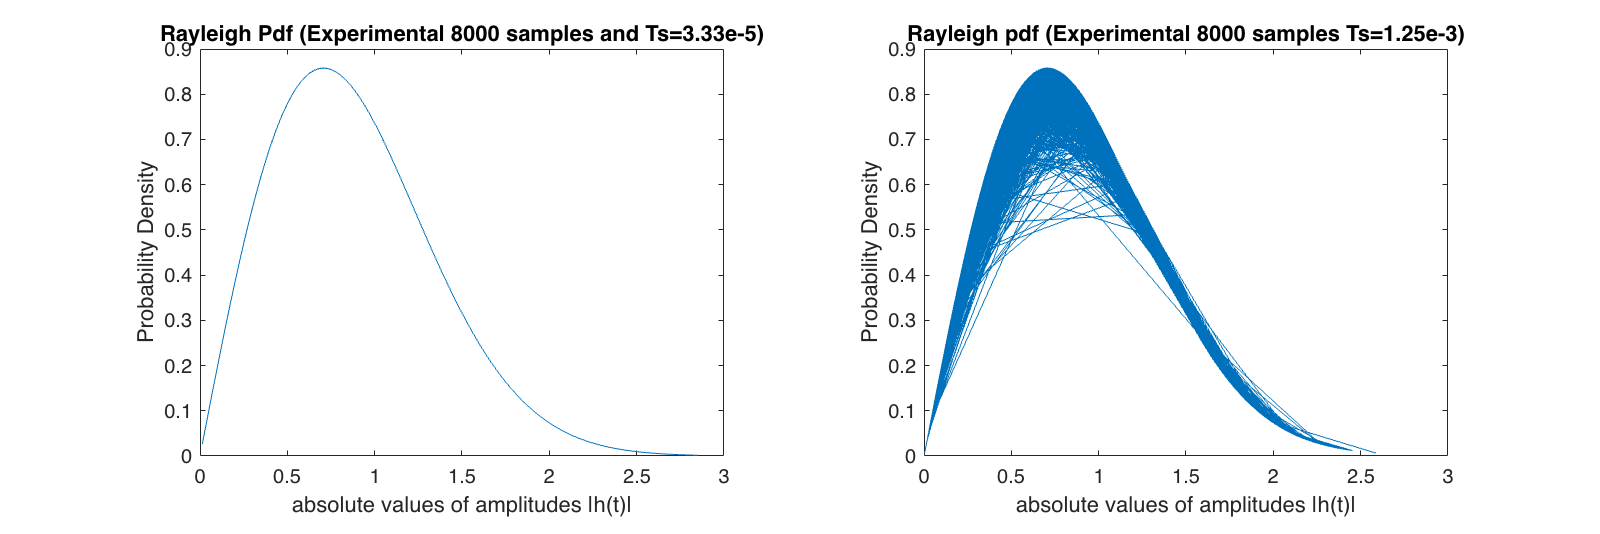


clc;
close all;
clear all;
M = 8;
N = 34;
Ts = 3.333e-5;
k = 1:1:8000;
syms k n;
format long g;
t = k*Ts;
hk = 0;
%STEP 1 Calculating h(k)
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    fdmax = 80;
    h = exp(1j*Bn)*(cos(2*pi*t*fdmax*cos(thetan)));
    hk = hk + h;
end
hk = vpa(hk); %Simplifying h(k) using variable precision aritmatic
%STEP 2 Finding Eo for Normalization of channel samples
Eo = 0;
for m = 1:1:8000
    temp = abs(power(subs(hk,k,m),2))/8000;
    Eo = Eo + temp;
end
Eo = vpa(Eo);
%STEP 3 Finding Normalized H(k)
hK = zeros(1,8000);
for a = 1:1:8000
    temp = subs(hk,k,a)/sqrt(Eo);
    hK(a) = temp;
end
x = abs(hK);
y = 2.*x.*exp(-(power(x,2)));


%for Ts = 1.24e-3
M = 8;
N = 34;
Ts = 1.25e-3;
k = 1:1:8000;
syms k n;
format long g;
t = k*Ts;
hk = 0;
%STEP 1 Calculating h(k)
for n = 1:1:8
    thetan = (2*pi*n)/N;
    Bn = (pi*n)/(M + 1);
    fdmax = 80;
    h = exp(1j*Bn)*(cos(2*pi*t*fdmax*cos(thetan)));
    hk = hk + h;
end
hk = vpa(hk); %Simplifying h(k) using variable precision aritmatic
%STEP 2 Finding Eo for Normalization of channel samples
Eo = 0;
for m = 1:1:8000
    temp = abs(power(subs(hk,k,m),2))/8000;
    Eo = Eo + temp;
end
Eo = vpa(Eo);
%STEP 3 Finding Normalized H(k)
hK = zeros(1,8000);
for a = 1:1:8000
    temp = subs(hk,k,a)/sqrt(Eo);
    hK(a) = temp;
end
set(gcf,'position',[1,1,2300,500])
tiledlayout(1,2)
nexttile
x_ = abs(hK);
y_ = 2.*x.*exp(-(power(x,2)));
plot(x,y)
title("Rayleigh Pdf (Experimental 8000 samples and Ts=3.33e-5)")
xlabel("absolute values of amplitudes |h(t)|")
ylabel("Probability Density")
nexttile
x_ = abs(hK);
y_ = 2.*x_.*exp(-(power(x_,2)));
plot(x_,y_)
title("Rayleigh pdf (Experimental 8000 samples Ts=1.25e-3)")
xlabel("absolute values of amplitudes |h(t)|")
ylabel("Probability Density")

**OBSERVATION: As we can see even though the value of Ts is different the pdf is similar. The Pdf does not tell us anything about how fast of slow the fading is**